# Modelado de sistemas fisicos - caída libre 

Segunda ley de Newton $F=m\;a$ 

$a=\frac{F}{m}$ =$\frac{F_s -F_l }{m}$


$$\begin{array}{l}
F=m\times a\\
a=\frac{F}{m}\\
\frac{\textrm{d}}{\textrm{d}t}v=\frac{F}{m}
\end{array}$$
   
$$\begin{array}{l}
F=\mathrm{Fd}+\mathrm{Fv}\;\\
\mathrm{Fd}=\mathrm{mg}\\
\mathrm{Fv}=-\mathrm{Cd}v^2 \\
\frac{d}{\textrm{d}t}v=g-\frac{\mathrm{Cd}}{m}v^2 
\end{array}$$
    
$$V\left(t\right)=\sqrt{\frac{\mathrm{gm}}{\mathrm{Cd}}}\mathrm{tanh}\left(\sqrt{\frac{\mathrm{gCd}}{m}t}\right)$$


## Analytical (closed-form) solution

syms v(t) g cd m 
eqn = diff(v,t) == g - (cd/m)*v^2 %diff es para poner derivada 

$$eqn(t) = \frac{\partial }{\partial t}v\left(t\right)=g-\frac{\mathrm{cd}\,{v\left(t\right)}^{2}}{m}$$

cnd = v(0) == 0 %el == solo se usa cuando es simbolico cnd= condiciciones iniciales

$$cnd = v\left(0\right)=0$$

vsym(t) = dsolve(eqn,cnd) % dsolve resuelve una ecuación simbolica 

$$vsym(t) = \frac{\sqrt{g}\,\sqrt{m}\,\tanh\left(\frac{\sqrt{\mathrm{cd}}\,\sqrt{g}\,t}{\sqrt{m}}\right)}{\sqrt{\mathrm{cd}}}$$


g = 9.81;    % m/s^2
m = 68.1;    % kg
cd = 0.25;   % kg/m

vel = subs(vsym) % subs sustituye todos los valores simbolicos de vSym x ctes

$$vel(t) = \frac{\sqrt{10}\,\sqrt{681}\,\sqrt{981}\,\tanh\left(\frac{\sqrt{10}\,\sqrt{681}\,\sqrt{981}\,t}{13620}\right)}{50}$$

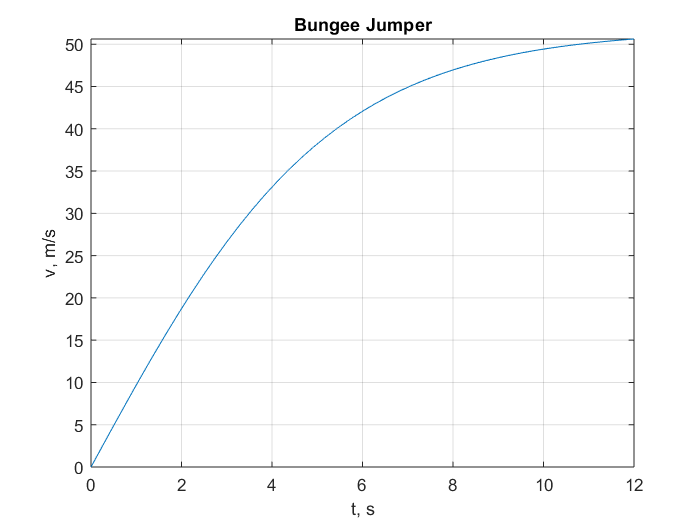


tf=12;  %s
fplot(vel,[0,tf]); % fplot grafica una función
title('Bungee Jumper');
xlabel('t, s');
ylabel('v, m/s');
grid on;
hold on; %para que 2 gráficas aparezcan

## Numerical (approximate) solution

Aproximación de la derivada como un limite

%f = @(v) g - (cd/m)*v^2        %el @ es para definir una función anonima
h = 1;
[t,v]= calculoVelocidad(0,tf,h,m,cd,g)

t =      0     1     2     3     4     5     6     7     8     9    10    11    12


v =                    0   9.810000000000000  19.266710352422908  27.713985947855505  34.704364005425504  40.092951079503798  44.001905828903631  46.704094828258611  48.506486628086172  49.678897622944092  50.428718221215163  50.902978054421041  51.200815151304781


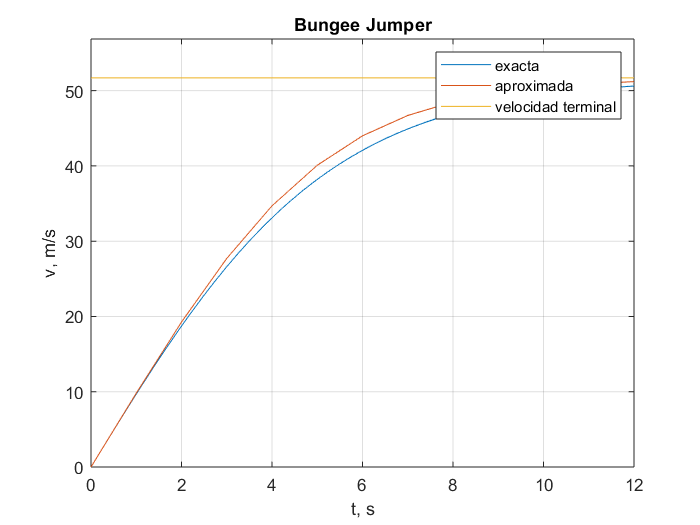

% t = 0:h:tf % vector de 1 renglon y varias columnas
% size(t);
% v = zeros(size(t)) %vector con puros ceros
% for i=1:1:length(v)-1
%     %v(i+1) = v(i) + f(v(i))*h
%     v(i+1) = v(i) + (g-(cd/m)*v(i)^2)*h;
% end
plot(t,v);  


velocidadTerminal = sqrt(g*m/cd); %me da la amplitud
cte = sqrt(cd*g/m); 
limite=velocidadTerminal*ones(size(t));
plot(t,limite);
legend('exacta', 'aproximada', 'velocidad terminal');
axis([0 tf 0 velocidadTerminal*1.1]);